% Created by: Anthony H. Le
% Last updated: 2022-02-09

% BME 6250 - Biomechanics II
% Homework 2
% Due date: 2022-02-15, 09:00 MST

## Problem 2a

close all; clear;

syms m k I1 I2 I3 C C2 Id
% m: mu
% k: kappa
% I1: invariant 1
% I2: invariant 2
% I3: invariant 3
% Id: identity tensor

% Id = diag([1 1 1])

W = (m/2) * (I1 - 3)^2 + (k/2) * (log(I3))^2

$$W = \frac{m\,{\left(I_{1}-3\right)}^{2}}{2}+\frac{k\,{\log\left(I_{3}\right)}^{2}}{2}$$

dW1 = diff(W, I1)

$$dW1 = \frac{m\,\left(2\,I_{1}-6\right)}{2}$$

dW2 = diff(W, I2)

$$dW2 = 0$$

dW3 = diff(W, I3)

$$dW3 = \frac{k\,\log\left(I_{3}\right)}{I_{3}}$$

% I1 = eval(trace(C))
% I2 = eval((1/2) * ((trace(C))^2 - trace(C^2)))
% I3 = eval(det(C))
% dI1 = Id
% dI2 = I1 * Id - C
% dI3 = I3 \ C
% S = subs(2 * (dW1 * dI1 + dW2 * dI2 + dW3 * dI3))
S = 2 * ((dW1 + I1 * dW2 + I2 * dW3) * Id - (dW2 + I1 * dW3) * C + dW3 * C^2)

$$S = 2\,\mathrm{Id}\,\left(\frac{m\,\left(2\,I_{1}-6\right)}{2}+\frac{I_{2}\,k\,\log\left(I_{3}\right)}{I_{3}}\right)+\frac{2\,C^{2}\,k\,\log\left(I_{3}\right)}{I_{3}}-\frac{2\,C\,I_{1}\,k\,\log\left(I_{3}\right)}{I_{3}}$$

## Problem 2b

close all; clear;

syms m k I1 I2 I3 C Id
% m: mu
% k: kappa
% I1: invariant 1
% I2: invariant 2
% I3: invariant 3
% Id: identity tensor

Id = diag([1 1 1])

Id =      1     0     0
     0     1     0
     0     0     1


F = Id

F =      1     0     0
     0     1     0
     0     0     1


C = transpose(F) * F

C =      1     0     0
     0     1     0
     0     0     1


W = (m/2) * (I1 - 3)^2 + (k/2) * (log(I3))^2

$$W = \frac{m\,{\left(I_{1}-3\right)}^{2}}{2}+\frac{k\,{\log\left(I_{3}\right)}^{2}}{2}$$

dW1 = diff(W, I1)

$$dW1 = \frac{m\,\left(2\,I_{1}-6\right)}{2}$$

dW2 = diff(W, I2)

$$dW2 = 0$$

dW3 = diff(W, I3)

$$dW3 = \frac{k\,\log\left(I_{3}\right)}{I_{3}}$$

I1 = trace(C)

I1 = 3

I2 = (1/2) * ((trace(C))^2 - trace(C^2))

I2 = 3

I3 = det(C)

I3 = 1

% dI1 = Id
% dI2 = I1 * Id - C
% dI3 = I3 \ C
% S = subs(2 * dW1 * dI1 + dW2 * dI2 + dW3 * dI3)
S = subs(2 * ((dW1 + I1 * dW2 + I2 * dW3) * Id - (dW2 + I1 * dW3) * C + dW3 * C^2))

$$S = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

## Problem 3

close all; clear; clc;

syms m Jm I1 I2 I3 Id lambda

W = -(m/2) * Jm * log(1 - ((I1 - 3) / Jm))

$$W = -\frac{\mathrm{Jm}\,m\,\log\left(1-\frac{I_{1}-3}{\mathrm{Jm}}\right)}{2}$$


dW1 = diff(W, I1)

$$dW1 = -\frac{m}{2\,\left(\frac{I_{1}-3}{\mathrm{Jm}}-1\right)}$$

dW2 = diff(W, I2)

$$dW2 = 0$$

dW3 = diff(W, I3)

$$dW3 = 0$$

F = diag([lambda lambda 1/(lambda^2)])

$$F = \left(\begin{array}{ccc} \lambda & 0 & 0\\ 0 & \lambda & 0\\ 0 & 0 & \frac{1}{\lambda^{2}} \end{array}\right)$$

B = F * transpose(F)

$$B = \left(\begin{array}{ccc} \lambda^{2} & 0 & 0\\ 0 & \lambda^{2} & 0\\ 0 & 0 & \frac{1}{\lambda^{4}} \end{array}\right)$$

Binv = inv(transpose(F)) * inv(F)

$$Binv = \left(\begin{array}{ccc} \frac{1}{\lambda^{2}} & 0 & 0\\ 0 & \frac{1}{\lambda^{2}} & 0\\ 0 & 0 & \lambda^{4} \end{array}\right)$$

J = det(F)

$$J = 1$$

% Id = diag([1 1 1])
T = (2/J) * (dW1 * B - I3 * dW2 * Binv + (I2 * dW2 + I3 * dW3) * Id)

$$T = \left(\begin{array}{ccc} -\frac{\lambda^{2}\,m}{\frac{I_{1}-3}{\mathrm{Jm}}-1} & 0 & 0\\ 0 & -\frac{\lambda^{2}\,m}{\frac{I_{1}-3}{\mathrm{Jm}}-1} & 0\\ 0 & 0 & -\frac{m}{\lambda^{4}\,\left(\frac{I_{1}-3}{\mathrm{Jm}}-1\right)} \end{array}\right)$$

S = (Jm/2) * F \ T \ transpose(F)

$$S = \left(\begin{array}{ccc} \frac{\mathrm{Jm}-I_{1}+3}{2\,m} & 0 & 0\\ 0 & \frac{\mathrm{Jm}-I_{1}+3}{2\,m} & 0\\ 0 & 0 & \frac{\mathrm{Jm}-I_{1}+3}{2\,m} \end{array}\right)$$

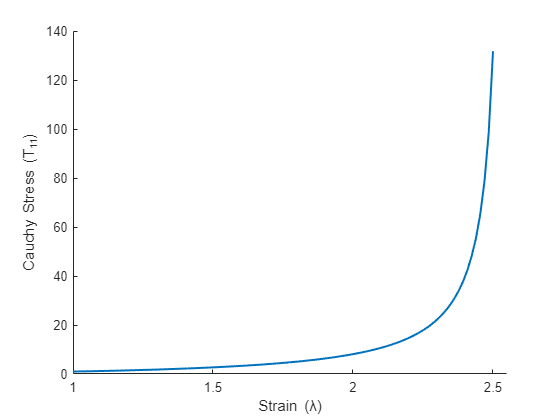

lambda = linspace(1, 2.5);
m = 1.0;
Jm = 10.0;
I1 = eval(trace(B));

T11 = subs(T(1, 1));

figure();
hold on;
plot(lambda, T11, "LineWidth", 1.5);
xlabel('Strain (\lambda)');
ylabel('Cauchy Stress (T_{11})')
xlim([1 2.55]);
hold off;

## Problem 4

close all; clear; clc;

syms h r I1 I2 I3 Id lambda

C1 = 185; % kPa
C2 = 28.2; % kPa
Cnh = 220; % kPa
Id = diag([1 1 1]);

Wmr = C1 * (I1 - 3) + C2 * (I2 - 3)

$$Wmr = 185\,I_{1}+\frac{141\,I_{2}}{5}-\frac{3198}{5}$$

Wnh = Cnh * (I1 - 3)

$$Wnh = 220\,I_{1}-660$$

F = diag([lambda lambda 1/(lambda^2)])

$$F = \left(\begin{array}{ccc} \lambda & 0 & 0\\ 0 & \lambda & 0\\ 0 & 0 & \frac{1}{\lambda^{2}} \end{array}\right)$$

B = F * transpose(F)

$$B = \left(\begin{array}{ccc} \lambda^{2} & 0 & 0\\ 0 & \lambda^{2} & 0\\ 0 & 0 & \frac{1}{\lambda^{4}} \end{array}\right)$$

Binv = inv(transpose(F)) * inv(F)

$$Binv = \left(\begin{array}{ccc} \frac{1}{\lambda^{2}} & 0 & 0\\ 0 & \frac{1}{\lambda^{2}} & 0\\ 0 & 0 & \lambda^{4} \end{array}\right)$$

## (a)

dWmr1 = diff(Wmr, I1)

$$dWmr1 = 185$$

dWmr2 = diff(Wmr, I2)

$$dWmr2 = \frac{141}{5}$$

dWmr3 = diff(Wmr, I3)

$$dWmr3 = 0$$


dWnh1 = diff(Wnh, I1)

$$dWnh1 = 220$$

dWnh2 = diff(Wnh, I2)

$$dWnh2 = 0$$

dWnh3 = diff(Wnh, I3)

$$dWnh3 = 0$$

I1 = eval(trace(B))

$$I1 = 2\,\lambda^{2}+\frac{1}{\lambda^{4}}$$

I2 = eval((1/2) * (trace(B)^2 - trace(B^2)))

$$I2 = \frac{{\left(2\,\lambda^{2}+\frac{1}{\lambda^{4}}\right)}^{2}}{2}-\lambda^{4}-\frac{1}{2\,\lambda^{8}}$$

I3 = eval(det(B))

I3 = 1

J = eval(det(F))

J = 1

Tmr = (2/J) * (dWmr1 * B - I3 * dWmr2 * Binv + (I2 * dWmr2 + I3 * dWmr3) * Id)

$$Tmr = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & 0 & 0\\ 0 & \sigma_{1} & 0\\ 0 & 0 & \frac{141\,{\left(2\,\lambda^{2}+\frac{1}{\lambda^{4}}\right)}^{2}}{5}+\frac{370}{\lambda^{4}}-\frac{564\,\lambda^{4}}{5}-\frac{141}{5\,\lambda^{8}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{141\,{\left(2\,\lambda^{2}+\frac{1}{\lambda^{4}}\right)}^{2}}{5}-\frac{282}{5\,\lambda^{2}}+370\,\lambda^{2}-\frac{282\,\lambda^{4}}{5}-\frac{141}{5\,\lambda^{8}} \end{array}$$

Tnh = (2/J) * (dWnh1 * B - I3 * dWnh2 * Binv + (I2 * dWnh2 + I3 * dWnh3) * Id)

$$Tnh = \left(\begin{array}{ccc} 440\,\lambda^{2} & 0 & 0\\ 0 & 440\,\lambda^{2} & 0\\ 0 & 0 & \frac{440}{\lambda^{4}} \end{array}\right)$$

## (b)

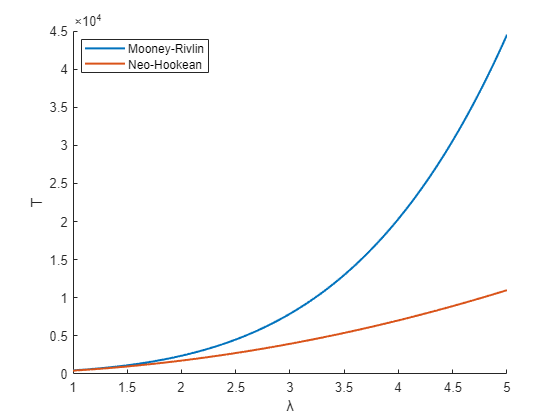

lambda = linspace(1, 5);

Tmr11 = subs(Tmr(1, 1));
Tnh11 = subs(Tnh(1, 1));

figure();
hold on;
plot(lambda, Tmr11, 'LineWidth', 1.5);
plot(lambda, Tnh11, 'LineWidth', 1.5);
xlabel('Strain (\lambda)');
ylabel('Cauchy Stress (T)')
legend('Mooney-Rivlin', 'Neo-Hookean', 'Location', 'best');
hold off;

## (c)

h0 = 1.5; % mm
r0 = 100; % mm

pmr = (2 * h * Tmr(1, 1)) / r

$$pmr = -\frac{2\,h\,\left(\frac{282}{5\,\lambda^{2}}-\frac{141\,{\left(2\,\lambda^{2}+\frac{1}{\lambda^{4}}\right)}^{2}}{5}-370\,\lambda^{2}+\frac{282\,\lambda^{4}}{5}+\frac{141}{5\,\lambda^{8}}\right)}{r}$$


pnh = (2 * h * Tnh(1, 1)) / r

$$pnh = \frac{880\,h\,\lambda^{2}}{r}$$

## (d)

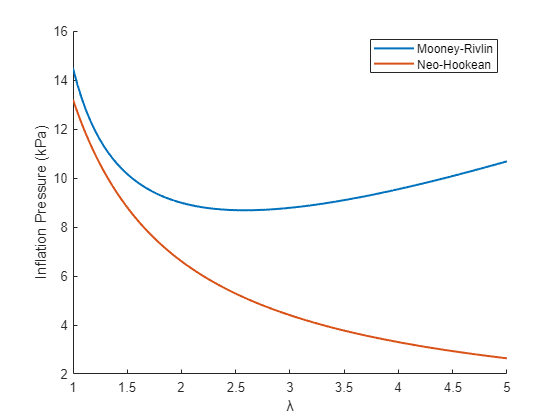

lambda = linspace(1, 5);
r = r0 .* lambda;
h = h0 ./ (lambda.^2);

pmr11 = subs(pmr);
pnh11 = subs(pnh);

figure();
hold on;
plot(lambda, pmr11, 'LineWidth', 1.5);
plot(lambda, pnh11, 'LineWidth', 1.5);
xlabel('Strain (\lambda)');
ylabel('Inflation Pressure (kPa)');
legend('Mooney-Rivlin', 'Neo-Hookean', 'Location', 'best');
hold off;